# Marginal cost data regression using polyfit function

## Load cleaned marginal cost data

load("cleanedQMCTables.mat");

### Split the data into four seasons

for n=1:numSelParts
    selMCTable = selCleanedPartQMCTables{n};
    selMCTable.Month = month(selMCTable.Date);
    isSpring = ismember(selMCTable.Month, [3,4,5]); 
    isSummer = ismember(selMCTable.Month, [6,7,8]);
    isAutumn = ismember(selMCTable.Month, [9,10,11]); 
    isWinter = ismember(selMCTable.Month, [12,1,2]);
    Season = zeros(size(selMCTable, 1), 1);
    Season(isSpring) = 1;
    Season(isSummer) = 2;
    Season(isAutumn) = 3;
    Season(isWinter) = 4;
    selMCTable.Season = categorical(Season);
    selCleanedPartQMCTables{n} = selMCTable;
end

n = 4;
partCleanedQMCTable = selCleanedPartQMCTables{n};
partCleanedQMCTable.AwardedSQ = partCleanedQMCTable.Awarded.^2;
partCleanedQMCTable.AwardedCB = partCleanedQMCTable.Awarded.^3;
partQM = fitlm(partCleanedQMCTable, 'MCMarket ~ 1+ Awarded + AwardedSQ + Season')

partQM = Linear regression model:
    MCMarket ~ 1 + Awarded + Season + AwardedSQ

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)        52.163        3.0743     16.967    3.3466e-59
    Awarded          -0.19414      0.014114    -13.755    1.2433e-40
    Season_2         -0.58802       0.25617    -2.2954      0.021848
    Season_3          -1.5176       0.28097    -5.4013    7.6838e-08
    Season_4           2.1762       0.33805     6.4374    1.6315e-10
    AwardedSQ      0.00026198    1.5714e-05     16.672    2.2302e-57


Number of observations: 1505, Error degrees of freedom: 1499
Root Mean Squared Error: 3.67
R-squared

partCleanedQMCTable.partQMFit = partQM.Fitted;
partCM = fitlm(partCleanedQMCTable, 'MCMarket ~ 1+ Awarded + AwardedSQ + AwardedCB+ Season')

partCM = Linear regression model:
    MCMarket ~ 1 + Awarded + Season + AwardedSQ + AwardedCB

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)        -48.55        9.0441    -5.3682    9.2055e-08
    Awarded           0.59255      0.068154     8.6942    9.0034e-18
    Season_2          0.40257       0.25919     1.5532       0.12059
    Season_3          -1.1356       0.27084     -4.193    2.9147e-05
    Season_4           1.2206       0.33354     3.6595    0.00026151
    AwardedSQ      -0.0016605    0.00016394    -10.129    2.2859e-23
    AwardedCB      1.4949e-06    1.2694e-07     11.776    1.1118e-30


Nu

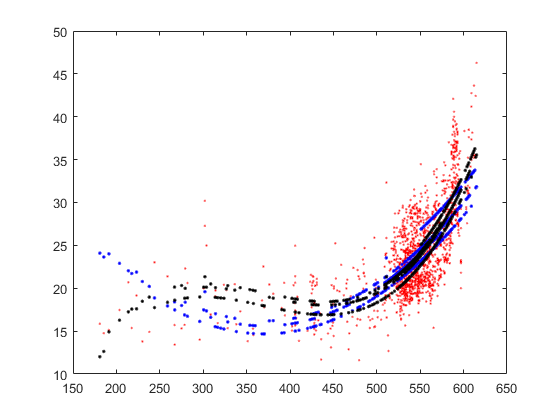

partCleanedQMCTable.partCMFit = partCM.Fitted;
scatter(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCMarket, 10, 'r.');
hold on;
scatter(partCleanedQMCTable.Awarded, partCleanedQMCTable.partQMFit, 'b.');
scatter(partCleanedQMCTable.Awarded, partCleanedQMCTable.partCMFit, 'k.');
hold off; box on;

## Fit quadratic relations of marginal cost and quantity

quadQMC = zeros(numSelParts, 3);
quadS = cell(numSelParts, 1);
quadMu = zeros(numSelParts, 2);
for n=1:numSelParts
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    [p, S, mu] = polyfit(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCMarket, 2);
    [y_fit, delta] = polyval(p, partCleanedQMCTable.Awarded, S, mu);
    selCleanedPartQMCTables{n}.MCQuadFit = y_fit;
    selCleanedPartQMCTables{n}.MCQuadDelta = delta;
    selCleanedPartQMCTables{n}.MCQuadError = selCleanedPartQMCTables{n}.MCMarket - selCleanedPartQMCTables{n}.MCQuadFit;
    quadQMC(n, :) = p;
    quadS{n} = S;
    quadMu(n, :) = mu.';
end

## Fit cubic relations of marginal cost and quantity

cubicQMC = zeros(numSelParts, 4);
cubicS = cell(numSelParts, 1);
cubicMu = zeros(numSelParts, 2);
for n=1:numSelParts
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    [p, S, mu] = polyfit(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCMarket, 3);
    [y_fit, delta] = polyval(p, partCleanedQMCTable.Awarded, S, mu);
    selCleanedPartQMCTables{n}.MCCubicFit = y_fit;
    selCleanedPartQMCTables{n}.MCCubicDelta = delta;
    selCleanedPartQMCTables{n}.MCCubicError = selCleanedPartQMCTables{n}.MCMarket - selCleanedPartQMCTables{n}.MCCubicFit;
    cubicQMC(n, :) = p;
    cubicS{n} = S;
    cubicMu(n, :) = mu.';
end

## Visualize quadratic relation

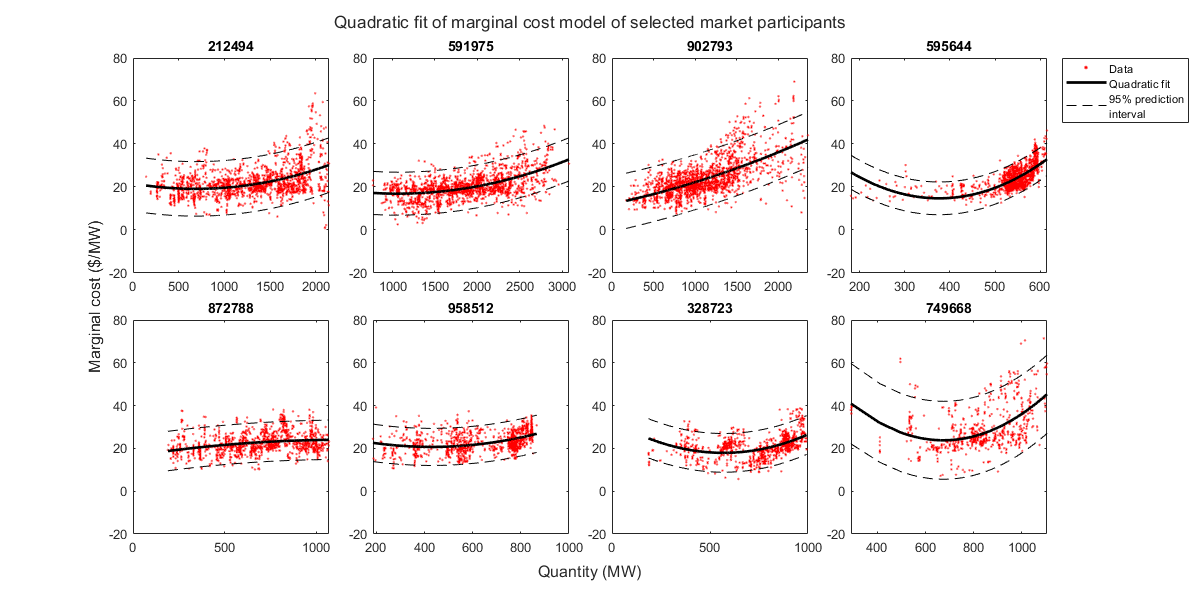

% Plot quantity vs marginal cost of selected market participants
plotColumn = 4;
t = tiledlayout(numSelParts/plotColumn, plotColumn, "TileSpacing","compact");
for n = 1:numSelParts
    nexttile;
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    partID = selPartIDs(n);
    scatter(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCMarket, 10, 'r.');
    hold on;
    % Plot quadratic estimation
    plot(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCQuadFit, 'k-', 'Linewidth', 2);
    quadUpper = partCleanedQMCTable.MCQuadFit + 2*partCleanedQMCTable.MCQuadDelta;
    quadLower = partCleanedQMCTable.MCQuadFit - 2*partCleanedQMCTable.MCQuadDelta;
    plot(partCleanedQMCTable.Awarded, quadUpper, 'k--', partCleanedQMCTable.Awarded, quadLower,'k--');
    hold off; box on;
    title(partID);
    ylim([-20, 80]);
    if n==plotColumn
        legend(["Data", "Quadratic fit", "95% prediction\newlineinterval"], "Location","bestoutside");
    end
end
xlabel(t, "Quantity (MW)");
ylabel(t, "Marginal cost ($/MW)");
title(t, "Quadratic fit of marginal cost model of selected market participants");
set(gcf, "Position", [50, 50, 1200, 600]);
saveas(gcf, "../model_output/figures/MCQuadPolyfit.png");

## Visualize cubic relation

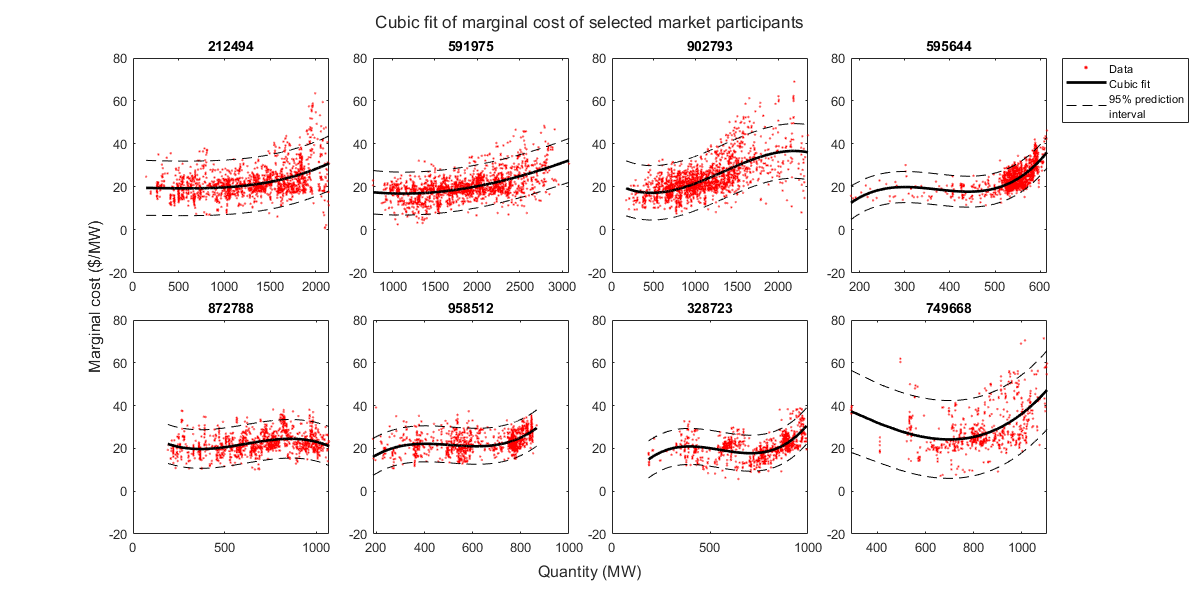

% Plot quantity vs marginal cost of selected market participants
plotColumn = 4;
t = tiledlayout(numSelParts/plotColumn, plotColumn, "TileSpacing","compact");
for n = 1:numSelParts
    nexttile;
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    partID = selPartIDs(n);
    scatter(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCMarket, 10, 'r.');
    hold on;
    % Plot cubic estimation
    plot(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCCubicFit, 'k-', "LineWidth", 2);
    cubicUpper = partCleanedQMCTable.MCCubicFit + 2*partCleanedQMCTable.MCCubicDelta;
    cubicLower = partCleanedQMCTable.MCCubicFit - 2*partCleanedQMCTable.MCCubicDelta;
    plot(partCleanedQMCTable.Awarded, cubicUpper, 'k--', partCleanedQMCTable.Awarded, cubicLower,'k--');
    hold off; box on;
    title(partID);
    ylim([-20, 80]);
    if n==plotColumn
        legend(["Data", "Cubic fit", "95% prediction\newlineinterval"], "Location","bestoutside");
    end
end
xlabel(t, "Quantity (MW)");
ylabel(t, "Marginal cost ($/MW)");
title(t, "Cubic fit of marginal cost of selected market participants");
set(gcf, "Position", [50, 50, 1200, 600]);
saveas(gcf, "../model_output/figures/MCCubicPolyfit.png");

## Show fitness of the quadratic and cubic models

corrQuad = zeros(numSelParts, 1);
corrCubic = zeros(numSelParts, 1);
RMSEQuad = zeros(numSelParts, 1);
RMSECubic = zeros(numSelParts, 1);
for n=1:numSelParts
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    % Calculate correlation coefficient
    quadR= corrcoef(partCleanedQMCTable.MCMarket, partCleanedQMCTable.MCQuadFit);
    cubicR = corrcoef(partCleanedQMCTable.MCMarket, partCleanedQMCTable.MCCubicFit);
    corrQuad(n)= quadR(1, 2);
    corrCubic(n) = cubicR(1, 2);
    % Calculate RMSE
    RMSEQuad(n) = sqrt(mean(partCleanedQMCTable.MCQuadError.^2));
    RMSECubic(n) = sqrt(mean(partCleanedQMCTable.MCCubicError.^2));
end
selPartIDs = categorical(selPartIDs);
selPartCorrPolyfit = table(selPartIDs, corrQuad, corrCubic, RMSEQuad, RMSECubic)

selPartCorrPolyfit = 8×5 table
    selPartIDs    corrQuad    corrCubic    RMSEQuad    RMSECubic
    __________    ________    _________    ________    _________

      212494      0.41861      0.41983      6.3307      6.3268  
      591975      0.53968      0.53975      4.9817      4.9814  
      902793      0.63816      0.64986      6.3867       6.305  
      595644      0.68828      0.72846      3.7907      3.5798  
      872788      0.28343      0.33959      4.5827      4.4947  
      958512      0.41381      0.46948      4.3246      4.1943  
      328723      0.46274      0.56655      4.5104      4.1926  
      749668       0.4991      0.50227      9.0714      9.0522  


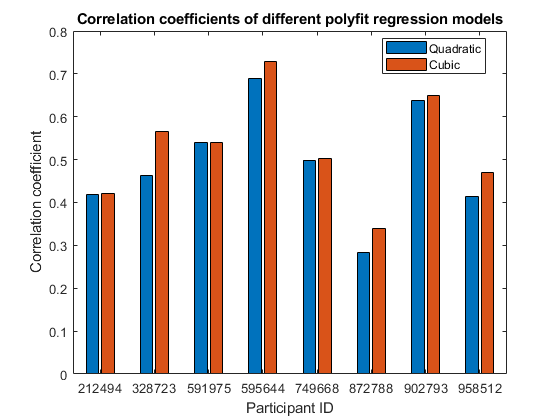

figure;
bar(selPartIDs, [corrQuad, corrCubic]);
legend(["Quadratic", "Cubic"], "Location","best");
xlabel("Participant ID");
ylabel("Correlation coefficient");
title("Correlation coefficients of different polyfit regression models");
saveas(gcf, "../model_output/figures/corrCoefPolyfit.png");

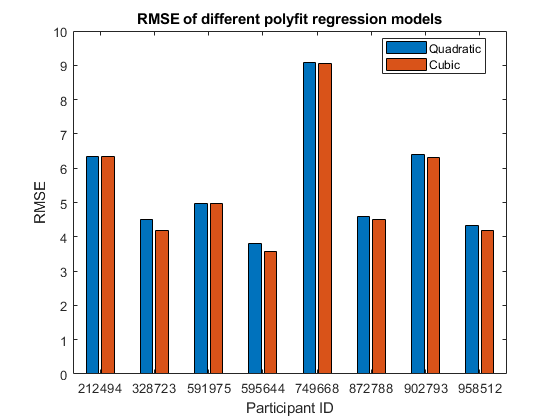

figure;
bar(selPartIDs, [RMSEQuad, RMSECubic]);
legend(["Quadratic", "Cubic"], "Location","best");
xlabel("Participant ID");
ylabel("RMSE");
title("RMSE of different polyfit regression models");
saveas(gcf, "../model_output/figures/RMSEPolyfit.png");

## Write fitted models to file

save("MCPolyfitQuad.mat", "quadQMC", "quadS", "quadMu", "-mat");
save("MCPolyfitCubic.mat", "cubicQMC", "cubicS", "cubicMu", "-mat");
save("MCPolyfitResults.mat", "selCleanedPartQMCTables", "-mat");
save("polyfitCorrRSME.mat", "selPartCorrPolyfit", "-mat");